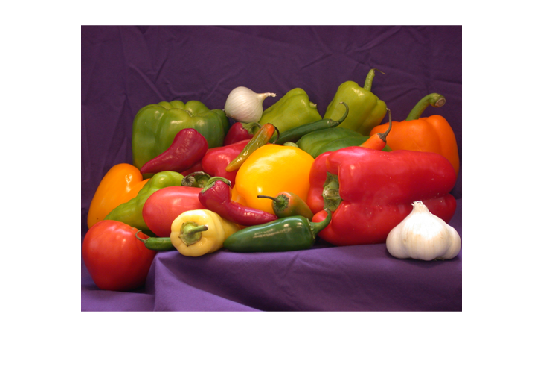

img=imread("peppers.png");
imshow(img);

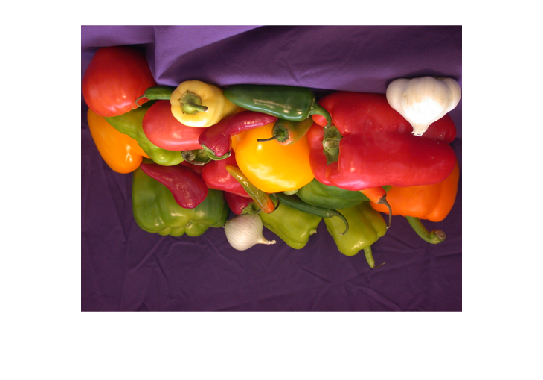

flipeedimg=flip(img);
imshow(flipeedimg);

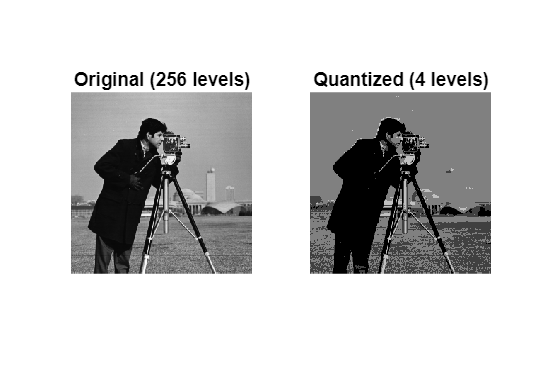



img = imread('cameraman.tif');
target_levels = 4; % We want only 4 shades of gray
gap = 256 / target_levels; 

% Quantize the image
quantized_img = floor(double(img) / gap) * gap;
quantized_img = uint8(quantized_img);

subplot(1,2,1); imshow(img); title('Original (256 levels)');
subplot(1,2,2); imshow(quantized_img); title('Quantized (4 levels)');

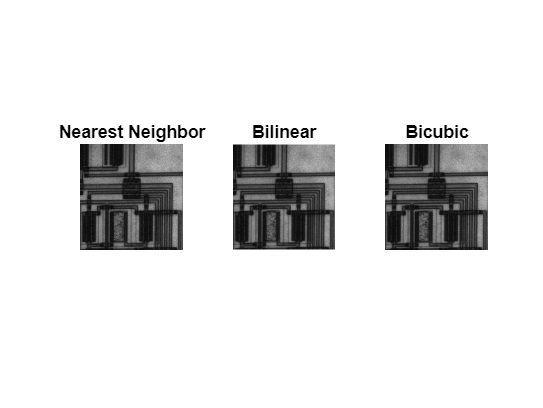


original = imread('circuit.tif');

% Scale factor: Zoom in 4x
scale = 4;

% 1. Nearest Neighbor
img_near = imresize(original, scale, 'nearest');

% 2. Bilinear
img_bilin = imresize(original, scale, 'bilinear');

% 3. Bicubic (MATLAB's default if you don't specify)
img_bicubic = imresize(original, scale, 'bicubic');

% Display Comparison
figure;
subplot(1,3,1); imshow(img_near); title('Nearest Neighbor');
subplot(1,3,2); imshow(img_bilin); title('Bilinear');
subplot(1,3,3); imshow(img_bicubic); title('Bicubic');

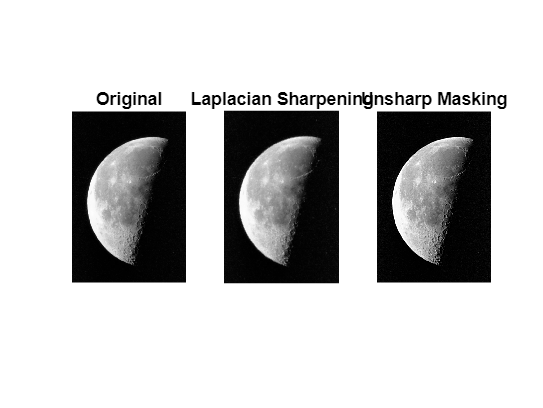


img = imread('moon.tif'); % Moon is great for sharpening tests

% Method 1: Laplacian
h_lap = fspecial('laplacian', 0.2); % Alpha controls shape
edges = imfilter(img, h_lap);
sharp_lap = img + edges; % Subtract edges to sharpen (logic varies by kernel sign)

% Method 2: Unsharp Masking (Built-in)
sharp_unsharp = imsharpen(img, 'Radius', 2, 'Amount', 1);

figure;
subplot(1,3,1); imshow(img); title('Original');
subplot(1,3,2); imshow(sharp_lap); title('Laplacian Sharpening');
subplot(1,3,3); imshow(sharp_unsharp); title('Unsharp Masking');

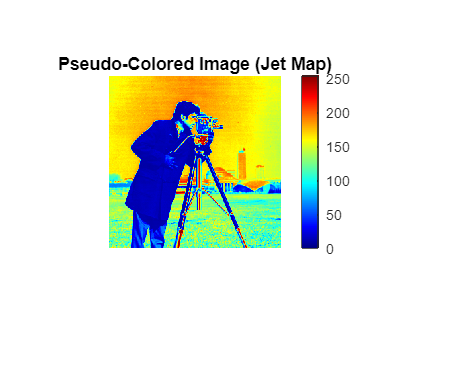


gray = imread('cameraman.tif');

figure;
imshow(gray);

% Apply a built-in colormap
colormap('jet'); % 'jet' is the rainbow map (Blue=Low, Red=High)
colorbar; % Show the scale
title('Pseudo-Colored Image (Jet Map)');